%% STEP 1 — Load & Preprocess Chest X-ray Images
clear; clc; close all;

% Path to your folder
folder = 'D:\project xray';

% Get all image files in that folder
images = dir(fullfile(folder, '*.png'));
if isempty(images)
    images = dir(fullfile(folder, '*.jpg'));
end

numImages = length(images);
fprintf('Found %d images in folder.\n', numImages);

Found 4 images in folder.


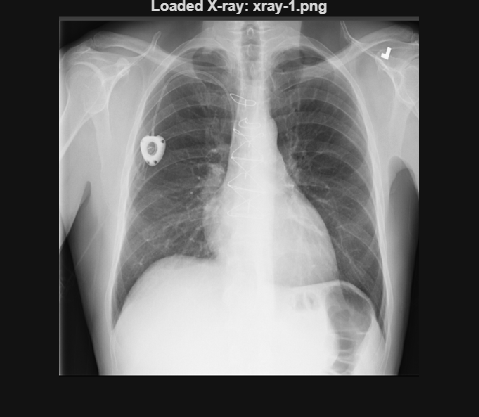

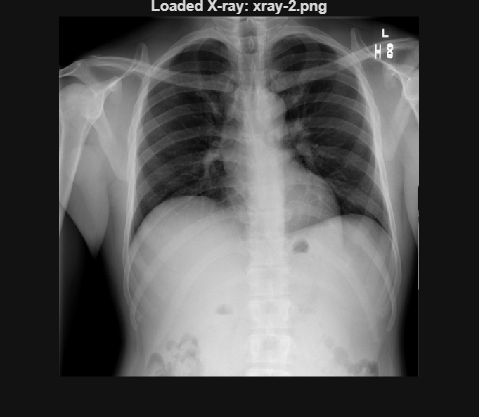

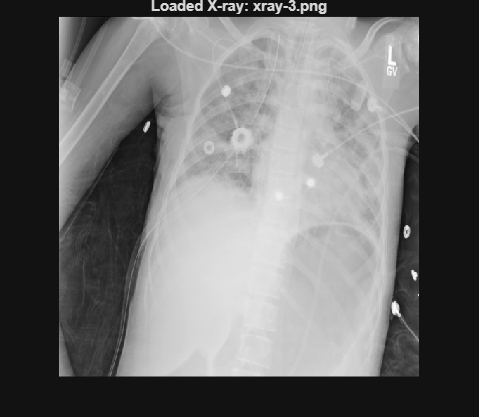

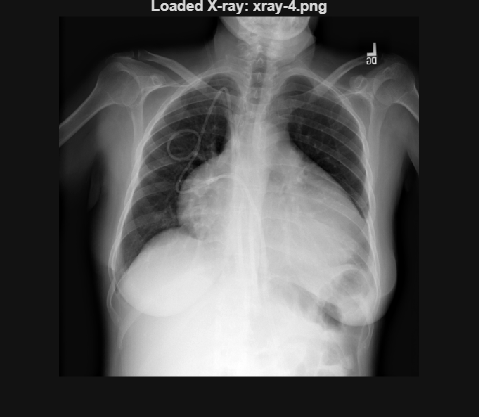


Xrays = cell(numImages, 1);

for i = 1:numImages
    imgPath = fullfile(folder, images(i).name);
    img = imread(imgPath);

    if size(img,3) == 3
        img = rgb2gray(img);
    end

    img = imresize(img, [512 512]);
    img = im2double(img);

    Xrays{i} = img;

    figure;
    imshow(img, []);
    title(['Loaded X-ray: ' images(i).name]);
end


disp('All images loaded and preprocessed successfully.');

All images loaded and preprocessed successfully.


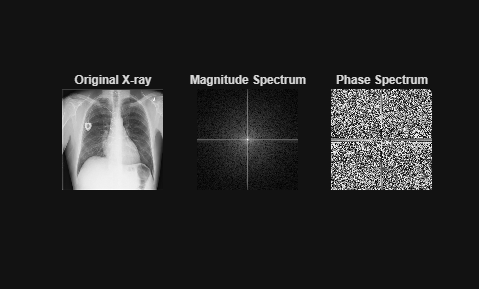




%% STEP 2 — FFT MAGNITUDE & PHASE
img = Xrays{1};   % Use first X-ray

F = fft2(img);
F_shifted = fftshift(F);

mag = log(1 + abs(F_shifted));   % magnitude spectrum
phase = angle(F_shifted);        % phase spectrum

figure;
subplot(1,3,1); imshow(img,[]); title('Original X-ray');
subplot(1,3,2); imshow(mag,[]); title('Magnitude Spectrum');
subplot(1,3,3); imshow(phase,[]); title('Phase Spectrum');

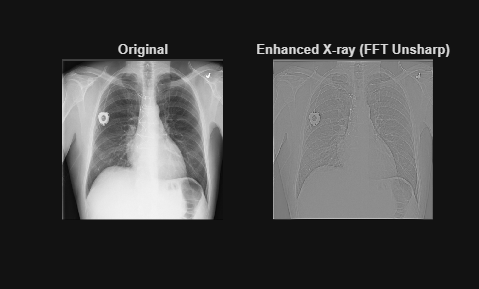




%% STEP 3 — IMPROVED ENHANCEMENT (from our conversation)
% Uses FFT high-pass + detail-add (unsharp mask)

D0 = 40;      % HPF cutoff radius
alpha = 0.4;  % Sharpening strength

[rows, cols] = size(img);
[u,v] = meshgrid(-floor(cols/2):ceil(cols/2)-1, -floor(rows/2):ceil(rows/2)-1);
D = sqrt(u.^2 + v.^2);

LP = exp(-(D.^2)/(2*D0^2));   % Gaussian LPF
HP = 1 - LP;                  % High-pass filter

% Extract detail
detail = real(ifft2(ifftshift(fftshift(fft2(img)) .* HP)));

% Normalize detail
detail = detail - mean(detail(:));
detail = detail / (std(detail(:)) + eps);

% Add detail to original (THIS FIXED YOUR GREY ISSUE)
enhanced = img + alpha * detail;

% Normalize cleanly
enhanced = mat2gray(enhanced);

figure;
subplot(1,2,1); imshow(img,[]); title('Original');
subplot(1,2,2); imshow(enhanced,[]); title('Enhanced X-ray (FFT Unsharp)');